# Leitor de arquivo no formato CRFS BIN.

Trata-se de leitor dos principais tipos de dados relacionados às versões 1, 2, 3, 4 e 5 de arquivo no formato CRFS BIN, gerado originalmente pela aplicação Logger, do RFeye.

Versão: **25/03/2022**

function specData = FileReader_CRFSBin_mat2(filename, ReadType, metaData)

    arguments
        filename char
        ReadType char   = 'SingleFile'
        metaData struct = []
    end

    global SpecInfo
    
    fileID = fopen(filename);
    if fileID == -1
        error('File not found.');
    end

    Format  = fread(fileID, 1, 'int32', 32);
    switch Format
        case 21;   FileFormat = 'CRFS Bin v.2-3';
        case 22;   FileFormat = 'CRFS Bin v.4';
        case 23;   FileFormat = 'CRFS Bin v.5';
        otherwise; error('Appears not to be a CRFS Bin file.')
    end

    rawData = fread(fileID, [1, inf], 'uint8=>uint8');
    fclose(fileID);
    
    switch ReadType
        case {'MetaData', 'SingleFile'}
            SpecInfo = struct('Node',         '', 'ThreadID',   '', 'MetaData',   [], 'ObservationTime', '', 'Samples',     [], ...
                              'Data',         {}, 'statsData',  [], 'FileFormat', '', 'TaskName',        '', 'Description', '', ...
                              'RelatedFiles', {}, 'RelatedGPS', {}, 'gps',        [], 'Blocks',          []);

            Fcn_MetaDataReader(filename, FileFormat, rawData);

            if strcmp(ReadType, 'SingleFile')
                Fcn_SpecDataReader(rawData, filename)
            end
            
        case 'SpecData'
            SpecInfo = metaData(1).Data;
            Fcn_SpecDataReader(rawData, filename);
    end
    
    specData = SpecInfo;
    clear global SpecInfo

end

Leitura de **metadados**.

function Fcn_MetaDataReader(filename, FileFormat, rawData)

    global GPS

    rawIndex     = strfind(char(rawData), 'UUUU');
    if isempty(rawIndex)
        return
    end
    
    DATATYPES    = [1:8, 21:22, 24, 40:42, 51, 60:69];
    SPECTYPES    = [4, 7:8, 60:65, 67:69];

    BlocksTable  = table('Size', [0, 6],                                                             ...
                         'VariableTypes', {'uint8', 'double', 'double', 'uint16', 'int8', 'uint32'}, ...
                         'VariableNames', {'ID', 'StartByte', 'StopByte', 'OffsetByte', 'OffsetLevel', 'DataPoints'});
    messageTable = table('Size', [0, 2],                      ...
                         'VariableTypes', {'double', 'cell'}, ...
                         'VariableNames', {'ThreadID', 'Message'});
    Hostname     = '';
    Taskname     = '';
    GPS          = struct('Status', 0, 'Latitude', -1, 'Longitude', -1, 'Count', 0, 'Location', '', 'Matrix', []);

    ii = 1;
    while ii <= numel(rawIndex)
        if ii == 1; ind1 = 1;
        else;       ind1 = rawIndex(ii-1)+4;
        end
        ind2     = rawIndex(ii)+3;
        rawArray = rawData(ind1:ind2);

        try
            jj = 0;
            while numel(rawArray) < 20
                jj = jj+1;
                
                ind2     = rawIndex(ii+jj)+3;
                rawArray = rawData(ind1:ind2);
            end

            ThreadID   = typecast(rawArray(1:4),  'uint32');
            BytesBlock = typecast(rawArray(5:8),  'uint32');
            DataType   = typecast(rawArray(9:12), 'uint32');

            if ~ismember(DataType, DATATYPES)
                error('DATATYPE')
            end

            tStart = tic;
            while numel(rawArray) < BytesBlock+20
                jj = jj+1;

                ind2     = rawIndex(ii+jj)+3;
                rawArray = rawData(ind1:ind2);

                if toc(tStart) > .1
                    error('BLOCKTIMEOUT')
                end
            end
    
            if numel(rawArray) ~= BytesBlock+20
                error('BLOCKSIZE')
            end
    
            EstimatedCheckSum  = typecast(rawArray(end-7:end-4), 'uint32');
            CalculatedCheckSum = uint32(sum(rawArray(1:end-8)));
    
            if EstimatedCheckSum ~= CalculatedCheckSum
                error('CHECKSUM')
            end

            switch DataType
                % Spectral data
                case 67; [ID, OffsetByte, OffsetLevel, DataPoints] = Read_DataType67(rawArray, ThreadID, DataType);
                case 68; [ID, OffsetByte, OffsetLevel, DataPoints] = Read_DataType68(rawArray, ThreadID, DataType);
                case 69; [ID, OffsetByte, OffsetLevel, DataPoints] = Read_DataType69(rawArray, ThreadID, DataType);
                
                case 63; [ID, OffsetByte, OffsetLevel, DataPoints] = Read_DataType63(rawArray, ThreadID, DataType);
                case 64; [ID, OffsetByte, OffsetLevel, DataPoints] = Read_DataType64(rawArray, ThreadID, DataType);
                case 65; [ID, OffsetByte, OffsetLevel, DataPoints] = Read_DataType65(rawArray, ThreadID, DataType);
                
                case 60; [ID, OffsetByte, OffsetLevel, DataPoints] = Read_DataType60(rawArray, ThreadID, DataType);
                case 61; [ID, OffsetByte, OffsetLevel, DataPoints] = Read_DataType61(rawArray, ThreadID, DataType);
                case 62; [ID, OffsetByte, OffsetLevel, DataPoints] = Read_DataType62(rawArray, ThreadID, DataType);

                case  4; [ID, OffsetByte, OffsetLevel, DataPoints] = Read_DataType04(rawArray, ThreadID, DataType);
                case  7; [ID, OffsetByte, OffsetLevel, DataPoints] = Read_DataType07(rawArray, ThreadID, DataType);
                case  8; [ID, OffsetByte, OffsetLevel, DataPoints] = Read_DataType08(rawArray, ThreadID, DataType);

                % GPS data    
                case {2, 40}
                    if DataType == 2; Read_DataType02(rawArray);
                    else;             Read_DataType40(rawArray);
                    end

                % Thread info
                case {3, 22, 24}
                    if    DataType == 24; Description = Read_DataType24(rawArray);
                    else;                 Description = Read_DataType22(rawArray);
                    end
                    messageTable(end+1, :) = {ThreadID, Description};
                        
                % Free text
                case {5, 41, 42}
                    % Informações desses blocos não compõem app.specData.
                    
                % Unit info
                case  1; [Hostname, Taskname] = Read_DataType01(rawArray);
                case 21; [Hostname, Taskname] = Read_DataType21(rawArray);

                % Others...
                otherwise
                    warning(['Leitor do bloco do tipo ' num2str(DataType) ' pendente de implementação.']);
                    ii = ii+jj+1; 
                    continue
            end

            ii = ii+jj+1;
            if ismember(DataType, SPECTYPES)
                BlocksTable(end+1,:) = {ID, ind1, ind2, OffsetByte, OffsetLevel, DataPoints};
            end
    
        catch ME
            switch ME.message
                case {'CHECKSUM', 'GERROR'}
                    ii = ii+jj+1;
                otherwise % 'DATATYPE', 'BLOCKTIMEOUT' and 'BLOCKSIZE'
                    ii = ii+1;
            end
        end
    end

    if GPS.Status
        GPS.Matrix    = GPS.Matrix / 1e+6;
        GPS.Count     = height(GPS.Matrix);
        GPS.Latitude  = mean(GPS.Matrix(:,1));
        GPS.Longitude = mean(GPS.Matrix(:,2));          
        
        GPS.Location  = FindCity(GPS);
    end

    Fcn_DataOrganization(filename, rawData, BlocksTable, Hostname, FileFormat, Taskname, messageTable)

end

Leitura de informações de **níveis apenas dos dados de blocos espectrais (incluso ocupação)**.

function Fcn_SpecDataReader(rawData, filename)

    global SpecInfo

    for ii = 1:numel(SpecInfo)
        SpecInfo(ii).Data  = {repmat(datetime([0 0 0 0 0 0], 'Format', 'dd/MM/yyyy HH:mm:ss'), 1, SpecInfo(ii).Samples), ...
                              zeros(SpecInfo(ii).MetaData.DataPoints, SpecInfo(ii).Samples, 'single')};
        
        for jj = 1:SpecInfo(ii).Samples
            Read_SpecData(ii, jj, rawData)
        end

        if ismember(SpecInfo(ii).MetaData.DataType, [4, 7])
            fileInfo = dir(filename);
            SpecInfo(ii).Data{1}(1:end) = linspace(datetime(fileInfo.date)-seconds(SpecInfo(ii).Samples-1), datetime(fileInfo.date), SpecInfo(ii).Samples);
        end
    end

end

# Funções auxiliares

function Fcn_DataOrganization(filename, rawData, BlocksTable, Hostname, FileFormat, Taskname, messageTable)

    global SpecInfo
    global GPS

    OCCTYPES = [8, 62, 65, 69];

    messageTable(~ismember(messageTable{:,1}, [SpecInfo.ThreadID]), :) = [];
    [~, file, ext] = fileparts(filename);

    for ii = 1:numel(SpecInfo)
        SpecInfo(ii).Node       = Hostname;
        SpecInfo(ii).FileFormat = FileFormat;
        SpecInfo(ii).TaskName   = Taskname;
        
        %% String com alguns dos metadados p/ simplificar leitura no app.
        %% Unidade
        switch SpecInfo(ii).MetaData.LevelUnit
            case 0; SpecInfo(ii).MetaData.LevelUnit = 1; Unit = 'dBm';
            case 1; SpecInfo(ii).MetaData.LevelUnit = 3; Unit = 'dBµV/m';
        end
        
        %% Resolução
        if SpecInfo(ii).MetaData.Resolution == -1
            SpecInfo(ii).MetaData.Resolution = [];
        end
        
        Resolution = '';
        if ~isempty(SpecInfo(ii).MetaData.Resolution)
            Resolution = sprintf('%.3f kHz', SpecInfo(ii).MetaData.Resolution/1000);
        end

        %% Processamento do traço.
        traceMode = '';
        if ismember(SpecInfo(ii).MetaData.DataType, OCCTYPES)
            traceMode = 'OCC';
        else
            switch SpecInfo(ii).MetaData.TraceMode
                case 0; traceMode = 'Single Measurement';
                case 1; traceMode = 'Mean';
                case 2; traceMode = 'Peak';
                case 3; traceMode = 'Minimum';
            end
        end

        %% Detector
        Detector = '';
        
        %% Antena.
        antennaName = '';
        if ~isempty(SpecInfo(ii).MetaData.Antenna)
            switch SpecInfo(ii).MetaData.Antenna
                case 0; antennaName = 'CRFS RFeye (Auto)';
                case 1; antennaName = 'CRFS RFeye Port 1';
                case 2; antennaName = 'CRFS RFeye Port 2';
                case 3; antennaName = 'CRFS RFeye Port 3';
                case 4; antennaName = 'CRFS RFeye Port 4';
            end
        end
        SpecInfo(ii).MetaData = rmfield(SpecInfo(ii).MetaData, {'Antenna', 'Description'});
        
        SpecInfo(ii).MetaData.metaString = {Unit, Resolution, traceMode, Detector, antennaName};
        
        if ~isempty(messageTable)
            SpecInfo(ii).Description = Read_Description(messageTable, SpecInfo(ii).ThreadID, ii);
        end
        
        SpecInfo(ii).gps             = rmfield(GPS, {'Count', 'Matrix'});
        SpecInfo(ii).RelatedGPS      = {GPS};
        SpecInfo(ii).RelatedFiles    = {[file ext]}; 

        SpecInfo(ii).Blocks          = BlocksTable(BlocksTable.ID == ii, 2:6);
        SpecInfo(ii).Samples         = height(SpecInfo(ii).Blocks);

        SpecInfo(ii).ObservationTime = Read_ObservationTime(rawData, ii, filename);
        
        %% SampleTime (only OCC info - integration factor)
        if ~isempty(SpecInfo(ii).MetaData.SampleTime)
            SpecInfo(ii).MetaData.SampleTime = SpecInfo(ii).MetaData.SampleTime / SpecInfo(ii).Samples;
        end
    end

    if ~issorted([SpecInfo.ThreadID])
        [~, indSort] = sort([SpecInfo.ThreadID]);
        SpecInfo     = SpecInfo(indSort);
    end

end

**Identificação de fluxo.**

function ID = Fcn_BinInfo(ThreadID, DataType, Description, FreqStart, FreqStop, Resolution, SampleTime, Threshold, AntennaID, TraceID, UnitID, NDATA)

    global SpecInfo
    
    Bin = struct('DataType',    DataType,   'ThreadID',    ThreadID,   ...
                 'FreqStart',   FreqStart,  'FreqStop',    FreqStop,   ...
                 'LevelUnit',   UnitID,     'DataPoints',  NDATA,      ...
                 'Resolution',  Resolution, 'SampleTime',  SampleTime, ...
                 'Threshold',   Threshold,  'TraceMode',   TraceID,    ...
                 'Detector',    [],         'Antenna',     AntennaID,  ...
                 'Description', Description);
    
    ID  = numel(SpecInfo)+1;
    ind = find([SpecInfo.ThreadID] == ThreadID);
    
    if ~isempty(ind)
        for ii = ind
            if isequal(rmfield(Bin, 'SampleTime'), rmfield(SpecInfo(ii).MetaData, 'SampleTime'))
                ID = ii;
                break
            end
        end
    end

    if ID > numel(SpecInfo)
        SpecInfo(ID).ThreadID    = double(ThreadID);
        SpecInfo(ID).MetaData    = Bin;
        SpecInfo(ID).Description = Description;

        SpecInfo(ID).MetaData.DataType   = double(SpecInfo(ID).MetaData.DataType);
        SpecInfo(ID).MetaData.ThreadID   = double(SpecInfo(ID).MetaData.ThreadID);
        SpecInfo(ID).MetaData.DataPoints = double(SpecInfo(ID).MetaData.DataPoints);
        SpecInfo(ID).MetaData.TraceMode  = double(SpecInfo(ID).MetaData.TraceMode);        
    else
        if ~isempty(Bin.SampleTime)
            SpecInfo(ID).MetaData.SampleTime = SpecInfo(ID).MetaData.SampleTime + Bin.SampleTime;
        end
    end

end

**TimeStamp**

function TimeStamp = Read_TimeStamp(rawArray, DataType)

    Date_Day     = double(rawArray(13));
    Date_Month   = double(rawArray(14));
    Date_Year    = double(rawArray(15)) + 2000;
    Time_Hours   = double(rawArray(17));
    Time_Minutes = double(rawArray(18));
    Time_Seconds = double(rawArray(19));

    if ismember(DataType, [60:65, 67:69])
        Time_nanoSec = double(typecast(rawArray(21:24), 'uint32'));
    else
        Time_nanoSec = 0;
    end
   
    TimeStamp    = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, (Time_Seconds+Time_nanoSec/1e+9)]);

end

**Observation time**

function ObservationTime = Read_ObservationTime(rawData, ind, filename)

    global SpecInfo

    if ismember(SpecInfo(ind).MetaData.DataType, [4, 7])
        fileInfo = dir(filename);

        StartTime = datestr(fileInfo.date, 'dd/mm/yyyy HH:MM:SS');
        StopTime  = datestr(datetime(fileInfo.date) + seconds(SpecInfo(ind).Samples-1), 'dd/mm/yyyy HH:MM:SS');

    else
        BytesOffset = 0;
        if SpecInfo(ind).MetaData.DataType == 8
            BytesOffset = 12;
        end

        ind1 = SpecInfo(ind).Blocks.StartByte(1) + BytesOffset;
        ind2 = SpecInfo(ind).Blocks.StopByte(1);
        StartTime = datestr(Read_TimeStamp(rawData(ind1:ind2), SpecInfo(ind).MetaData.DataType), 'dd/mm/yyyy HH:MM:SS');

        ind1 = SpecInfo(ind).Blocks.StartByte(end) + BytesOffset;
        ind2 = SpecInfo(ind).Blocks.StopByte(end);
        StopTime  = datestr(Read_TimeStamp(rawData(ind1:ind2), SpecInfo(ind).MetaData.DataType), 'dd/mm/yyyy HH:MM:SS');
    end

    ObservationTime = sprintf('%s - %s', StartTime, StopTime);
    
end

**Description (CRFS Bin v. 3-4)**

function Description = Read_Description(messageTable, ThreadID, ii)

    global SpecInfo

    Description = '';
    if isequal(messageTable.ThreadID', [SpecInfo.ThreadID])
        Description = messageTable.Message{ii};

    else
        ind = find(messageTable.ThreadID == ThreadID);

        if ~isempty(ind)
            if numel(ind) == 1
                Description = messageTable.Message{ind};
            else
                Description = jsonencode(messageTable(ind,:));
            end
        end
    end

end

# Tipos de dados.

A seguir é apresentada tabela com os tipos de dados gerados pelo RFEye Logger. A versão dos tipos de dados, diga-se, é indicada no início do *script* carregado no Logger, na forma "file_version = 5". E essa informação é recuperada logo no início do arquivo binário, nos campos "Format" (4 bytes em *int32*) e "sFormat" (32 bytes em *string*), da seguinte forma: Format = 21 (file_version = 3), 22 (file_version = 4) e 23 (file_version = 5).

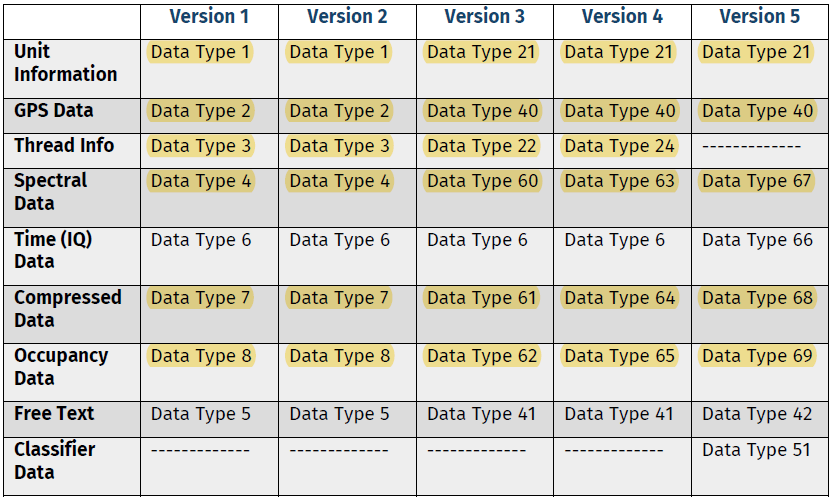

Em destaque os tipos de dados implantados neste algoritmo para possibilitar a criação de variáveis do appAnálise - app.metaData e app.specData. 

## **Unit Info: [1, 21]**

DataType 1

function [Hostname, Taskname] = Read_DataType01(rawArray)
    
    Hostname      = deblank(char(rawArray(13:28)));
    Hostname(1:2) = upper(Hostname(1:2));
    Hostname      = erase(Hostname, '_');
    
    Taskname      = 'Unknown info';
    
end

DataType 21

function [Hostname, Taskname] = Read_DataType21(rawArray)
    
    Hostname      = deblank(char(rawArray(13:28)));
    Hostname(1:2) = upper(Hostname(1:2));
    Hostname      = erase(Hostname, '_');

    TEXT1LEN      = typecast(rawArray(29:32), 'uint32');
    TEXT2LEN      = typecast(rawArray(33+TEXT1LEN:36+TEXT1LEN), 'uint32');

    Taskname      = deblank(char(rawArray(37+TEXT1LEN:36+TEXT1LEN+TEXT2LEN)));
    Taskname      = erase(Taskname, '_');
    
end

## **GPS Data: [2, 40]**

DataType 2

function Read_DataType02(rawArray)

    global GPS
    
    Status    = double(typecast(rawArray(23:24), 'uint16'));
    Latitude  = double(typecast(rawArray(27:30), 'int32'));
    Longitude = double(typecast(rawArray(31:34), 'int32'));

    if Status
        GPS.Status          = 1;
        GPS.Matrix(end+1,:) = [Latitude, Longitude];
    end
    
end

DataType 40

A leitura se restringe àquilo que compõe specData, não englobando, na presente data, a informação dos campos Timestamp, Satellites, Heading, Speed e Altitude. A seguir são apresentados trechos do código, sendo a parte comentada exatamente àquela não está sendo lida.

function Read_DataType40(rawArray)

    global GPS
    
    Status    = double(rawArray(33));
    Latitude  = double(typecast(rawArray(37:40), 'int32'));
    Longitude = double(typecast(rawArray(41:44), 'int32'));

    if Status
        GPS.Status          = 1;
        GPS.Matrix(end+1,:) = [Latitude, Longitude];
    end
    
end

## **Thread Info: [3, 22, 24]**

DataTypes 3/22

function Description = Read_DataType22(rawArray)
    
    TEXTLEN     = typecast(rawArray(13:16), 'uint32');
    Description = deblank(char(rawArray(17:16+TEXTLEN)));
    
end

DataType 24

function Description = Read_DataType24(rawArray)
    
    TEXTLEN     = typecast(rawArray(17:20), 'uint32');
    Description = deblank(char(rawArray(21:20+TEXTLEN)));
    
end

## **Spectral Data: [4, 7, 8, 60, 61, 62, 63, 64, 65, 67, 68, 69]**

#### Leitura de metadados

DataType 4

function [ID, OffsetByte, OffsetLevel, NDATA] = Read_DataType04(rawArray, ThreadID, DataType)

    FreqStart   = double(typecast(rawArray(13:14), 'uint16')) * 1e+6;               % (01:02) (2 bytes)
    FreqStop    = double(typecast(rawArray(15:16), 'uint16')) * 1e+6;               % (03:04) (2 bytes)
    OffsetLevel = typecast(rawArray(17), 'int8');                                   % (05:05) (1 byte )
    AntennaID   = rawArray(18);                                                     % (06:06) (1 byte )
    TraceID     = rawArray(19);                                                     % (07:07) (1 byte )
    NDATA       = typecast(rawArray(21:24), 'uint32');                              % (09:12) (4 bytes)    

    Description = '';
    Resolution  = [];
    SampleTime  = [];
    Threshold   = [];
    UnitID      = 0;

    ID          = Fcn_BinInfo(ThreadID, DataType, Description, FreqStart, FreqStop, Resolution, SampleTime, Threshold, AntennaID, TraceID, UnitID, NDATA);
    OffsetByte  = 24;

end

DataType 7 (Compressed)

function [ID, OffsetByte, OffsetLevel, NCDATA] = Read_DataType07(rawArray, ThreadID, DataType)

    FreqStart   = double(typecast(rawArray(13:16), 'uint32')) * 1e+6;               % (01:04) (4 bytes)
    FreqStop    = double(typecast(rawArray(17:20), 'uint32')) * 1e+6;               % (05:08) (4 bytes)
    OffsetLevel = typecast(rawArray(21:24),  'int32');                              % (09:12) (4 bytes)
    Threshold   = double(typecast(rawArray(25:28), 'int32'));                       % (13:16) (4 bytes)
    AntennaID   = typecast(rawArray(29:32), 'uint32');                              % (17:20) (4 bytes)
    TraceID     = typecast(rawArray(33:36), 'uint32');                              % (21:24) (4 bytes)
    NDATA       = typecast(rawArray(41:44), 'uint32');                              % (29:32) (4 bytes)    
    NCDATA      = typecast(rawArray(49:52), 'uint32');                              % (37:40) (4 bytes)    

    Description = '';
    Resolution  = [];
    SampleTime  = [];
    UnitID      = 0;

    ID          = Fcn_BinInfo(ThreadID, DataType, Description, FreqStart, FreqStop, Resolution, SampleTime, Threshold, AntennaID, TraceID, UnitID, NDATA);
    OffsetByte  = 52;

end

DataType 8 (OCC)

function [ID, OffsetByte, OffsetLevel, NDATA] = Read_DataType08(rawArray, ThreadID, DataType)

    FreqStart   = double(typecast(rawArray(13:16), 'uint32')) * 1e+6;               % (01:04) (4 bytes)
    FreqStop    = double(typecast(rawArray(17:20), 'uint32')) * 1e+6;               % (05:08) (4 bytes)
    Threshold   = double(typecast(rawArray(21:24),  'int32'));                      % (09:12) (4 bytes)
    SampleTime  = double(typecast(rawArray(33:36), 'uint32'));                      % (21:24) (4 bytes)
    AntennaID   = typecast(rawArray(37:40), 'uint32');                              % (25:28) (4 bytes)
    NDATA       = typecast(rawArray(49:52), 'uint32');                              % (37:40) (4 bytes)

    Description = '';
    Resolution  = [];
    TraceID     = [];
    UnitID      = 0;

    ID          = Fcn_BinInfo(ThreadID, DataType, Description, FreqStart, FreqStop, Resolution, SampleTime, Threshold, AntennaID, TraceID, UnitID, NDATA);
    OffsetByte  = 52;
    OffsetLevel = 0;

end

DataType 60

function [ID, OffsetByte, OffsetLevel, NDATA] = Read_DataType60(rawArray, ThreadID, DataType)

    % v.3 commom fields
    auxF0 = double(typecast(rawArray(25:28), 'uint32'));                            % (13:16) (4 bytes)
    auxF1 = double(typecast(rawArray(29:32), 'uint32'));                            % (17:20) (4 bytes)
    expF0 = double(typecast(rawArray(33:33), 'int8'));                              % (21:21) (1 byte )

    FreqStart  = auxF0 * 10^expF0;
    FreqStop   = auxF1 * 10^expF0;

    AntennaID   = rawArray(34);                                                     % (22:22) (1 byte )

    GERROR      = typecast(rawArray(35), 'int8');                                   % (23:23) (1 byte )
    if GERROR ~= -1
        error('GERROR');
    end

    % others fields...
    TraceID     = rawArray(39);                                                     % (27:27) (1 byte )
    OffsetLevel = typecast(rawArray(41), 'int8');                                   % (29:29) (1 byte )
    NTUN        = typecast(rawArray(43:44), 'uint16');                              % (31:32) (2 bytes)
    NAGC        = typecast(rawArray(45:46), 'uint16');                              % (33:34) (2 bytes)
    NDATA       = typecast(rawArray(49:52), 'uint32');                              % (37:40) (4 bytes)

    Description = '';
    Resolution  = [];
    SampleTime  = [];
    Threshold   = [];
    UnitID      = 0;

    ID          = Fcn_BinInfo(ThreadID, DataType, Description, FreqStart, FreqStop, Resolution, SampleTime, Threshold, AntennaID, TraceID, UnitID, NDATA);
    OffsetByte  = 52 + 4*NTUN + NAGC;

end

DataType 61 (Compressed)

function [ID, OffsetByte, OffsetLevel, NCDATA] = Read_DataType61(rawArray, ThreadID, DataType)

    % v.3 commom fields
    auxF0 = double(typecast(rawArray(25:28), 'uint32'));                            % (13:16) (4 bytes)
    auxF1 = double(typecast(rawArray(29:32), 'uint32'));                            % (17:20) (4 bytes)
    expF0 = double(typecast(rawArray(33:33), 'int8'));                              % (21:21) (1 byte )

    FreqStart  = auxF0 * 10^expF0;
    FreqStop   = auxF1 * 10^expF0;

    AntennaID   = rawArray(34);                                                     % (22:22) (1 byte )

    GERROR      = typecast(rawArray(35), 'int8');                                   % (23:23) (1 byte )
    if GERROR ~= -1
        error('GERROR');
    end

    % others fields...
    TraceID     = rawArray(39);                                                     % (27:27) (1 byte )
    OffsetLevel = typecast(rawArray(41), 'int8');                                   % (29:29) (1 byte )
    NTUN        = typecast(rawArray(43:44), 'uint16');                              % (31:32) (2 bytes)
    NAGC        = typecast(rawArray(45:46), 'uint16');                              % (33:34) (2 bytes)
    NCDATA      = typecast(rawArray(49:52), 'uint32');                              % (37:40) (4 bytes)

    Threshold   = double(typecast(rawArray(53:56), 'int32'));                       % (41:44) (4 bytes)
    NDATA       = typecast(rawArray(57:60), 'uint32');                              % (45:48) (4 bytes)

    Description = '';
    Resolution  = [];
    SampleTime  = [];
    UnitID      = 0;

    ID          = Fcn_BinInfo(ThreadID, DataType, Description, FreqStart, FreqStop, Resolution, SampleTime, Threshold, AntennaID, TraceID, UnitID, NDATA);
    OffsetByte  = 60 + 4*NTUN + NAGC;

end

DataType 62 (OCC)

function [ID, OffsetByte, OffsetLevel, NDATA] = Read_DataType62(rawArray, ThreadID, DataType)

    % v.3 commom fields
    auxF0 = double(typecast(rawArray(25:28), 'uint32'));                            % (13:16) (4 bytes)
    auxF1 = double(typecast(rawArray(29:32), 'uint32'));                            % (17:20) (4 bytes)
    expF0 = double(typecast(rawArray(33:33), 'int8'));                              % (21:21) (1 byte )

    FreqStart  = auxF0 * 10^expF0;
    FreqStop   = auxF1 * 10^expF0;

    AntennaID   = rawArray(34);                                                     % (22:22) (1 byte )

    GERROR      = typecast(rawArray(35), 'int8');                                   % (23:23) (1 byte )
    if GERROR ~= -1
        error('GERROR');
    end

    % others fields...
    Threshold   = double(typecast(rawArray(39:40), 'int16'));                       % (27:28) (2 bytes)
    SampleTime  = double(typecast(rawArray(45:48), 'uint32'));                      % (33:36) (4 bytes)
    NDATA       = typecast(rawArray(53:56), 'uint32');                              % (41:44) (4 bytes)

    Description = '';
    Resolution  = [];
    TraceID     = [];
    UnitID      = 0;

    ID          = Fcn_BinInfo(ThreadID, DataType, Description, FreqStart, FreqStop, Resolution, SampleTime, Threshold, AntennaID, TraceID, UnitID, NDATA);
    OffsetByte  = 56;
    OffsetLevel = 0;

end

DataType 63

function [ID, OffsetByte, OffsetLevel, NDATA] = Read_DataType63(rawArray, ThreadID, DataType)

    % v.4 commom fields
    IntegerPart = double(typecast(rawArray(25:26), 'uint16'));                      % (13:14) (2 bytes)
    DecimalPart = double(typecast(rawArray(27:30), 'int32'));                       % (15:18) (4 bytes)
    FreqStart   = (IntegerPart + DecimalPart / 1e+9) * 1e+6;

    IntegerPart = double(typecast(rawArray(31:32), 'uint16'));                      % (19:20) (2 bytes)
    DecimalPart = double(typecast(rawArray(33:36), 'int32'));                       % (21:24) (4 bytes)
    FreqStop    = (IntegerPart + DecimalPart / 1e+9) * 1e+6;

    % others fields...
    AntennaID   = rawArray(49);                                                     % (37:37) (1 byte )
    TraceID     = rawArray(50);                                                     % (38:38) (1 byte )
    UnitID      = rawArray(51);                                                     % (39:39) (1 byte )
    OffsetLevel = typecast(rawArray(52), 'int8');                                   % (40:40) (1 byte )

    GERROR      = typecast(rawArray(53), 'int8');                                   % (41:41) (1 byte )
    if GERROR ~= -1
        error('GERROR');
    end

    NTUN        = typecast(rawArray(56:57), 'uint16');                              % (44:45) (2 bytes)
    NAGC        = typecast(rawArray(58:59), 'uint16');                              % (46:47) (2 bytes)
    NDATA       = typecast(rawArray(61:64), 'uint32');                              % (49:52) (4 bytes)

    Description = '';
    Resolution  = [];
    SampleTime  = [];
    Threshold   = [];
    
    ID          = Fcn_BinInfo(ThreadID, DataType, Description, FreqStart, FreqStop, Resolution, SampleTime, Threshold, AntennaID, TraceID, UnitID, NDATA);
    OffsetByte  = 64 + 4*NTUN + NAGC;

end

DataType 64 (Compressed)

function [ID, OffsetByte, OffsetLevel, NCDATA] = Read_DataType64(rawArray, ThreadID, DataType)

    % v.4 commom fields
    IntegerPart = double(typecast(rawArray(25:26), 'uint16'));                      % (13:14) (2 bytes)
    DecimalPart = double(typecast(rawArray(27:30), 'int32'));                       % (15:18) (4 bytes)
    FreqStart   = (IntegerPart + DecimalPart / 1e+9) * 1e+6;

    IntegerPart = double(typecast(rawArray(31:32), 'uint16'));                      % (19:20) (2 bytes)
    DecimalPart = double(typecast(rawArray(33:36), 'int32'));                       % (21:24) (4 bytes)
    FreqStop    = (IntegerPart + DecimalPart / 1e+9) * 1e+6;

    % others fields...
    AntennaID   = rawArray(49);                                                     % (37:37) (1 byte )
    TraceID     = rawArray(50);                                                     % (38:38) (1 byte )
    UnitID      = rawArray(51);                                                     % (39:39) (1 byte )
    OffsetLevel = typecast(rawArray(52), 'int8');                                   % (40:40) (1 byte )

    GERROR      = typecast(rawArray(53), 'int8');                                   % (41:41) (1 byte )
    if GERROR ~= -1
        error('GERROR');
    end

    NTUN        = typecast(rawArray(56:57), 'uint16');                              % (44:45) (2 bytes)
    NAGC        = typecast(rawArray(58:59), 'uint16');                              % (46:47) (2 bytes)
    NCDATA      = typecast(rawArray(61:64), 'uint32');                              % (49:52) (4 bytes)

    Threshold   = double(typecast(rawArray(65:68), 'int32'));                       % (53:56) (4 bytes)
    NDATA       = typecast(rawArray(69:72), 'uint32');                              % (57:60) (4 bytes)

    Description = '';
    Resolution  = [];
    SampleTime  = [];
    
    ID          = Fcn_BinInfo(ThreadID, DataType, Description, FreqStart, FreqStop, Resolution, SampleTime, Threshold, AntennaID, TraceID, UnitID, NDATA);
    OffsetByte  = 72 + 4*NTUN + NAGC;

end

DataType 65 (OCC)

function [ID, OffsetByte, OffsetLevel, NDATA] = Read_DataType65(rawArray, ThreadID, DataType)

    % v.4 commom fields
    IntegerPart = double(typecast(rawArray(25:26), 'uint16'));                      % (13:14) (2 bytes)
    DecimalPart = double(typecast(rawArray(27:30), 'int32'));                       % (15:18) (4 bytes)
    FreqStart   = (IntegerPart + DecimalPart / 1e+9) * 1e+6;

    IntegerPart = double(typecast(rawArray(31:32), 'uint16'));                      % (19:20) (2 bytes)
    DecimalPart = double(typecast(rawArray(33:36), 'int32'));                       % (21:24) (4 bytes)
    FreqStop    = (IntegerPart + DecimalPart / 1e+9) * 1e+6;

    % others fields...
    AntennaID   = rawArray(45);                                                     % (33:33) (1 byte )
    UnitID      = typecast(rawArray(47:48), 'uint16');                              % (35:36) (2 bytes)

    GERROR      = typecast(rawArray(49), 'int8');                                   % (37:37) (1 byte )
    if GERROR ~= -1
        error('GERROR');
    end
    
    Threshold   = double(typecast(rawArray(53:54), 'int16'));                       % (41:42) (2 bytes)
    SampleTime  = double(typecast(rawArray(55:56), 'uint16'));                      % (43:44) (2 bytes)
    NDATA       = typecast(rawArray(57:60), 'uint32');                              % (45:48) (4 bytes)

    Description = '';
    Resolution  = [];
    TraceID     = [];
    
    ID          = Fcn_BinInfo(ThreadID, DataType, Description, FreqStart, FreqStop, Resolution, SampleTime, Threshold, AntennaID, TraceID, UnitID, NDATA);
    OffsetByte  = 60;
    OffsetLevel = 0;

end

DataType 67

function [ID, OffsetByte, OffsetLevel, NDATA] = Read_DataType67(rawArray, ThreadID, DataType)

    % v.5 commom fields
    DESCLEN     = double(typecast(rawArray(33:36), 'uint32'));                      % (21:24)           (      4 bytes)
    Description = deblank(char(rawArray(37:36+DESCLEN)));                           % (25:24+DESCLEN)   (DESCLEN bytes)

    IntegerPart = double(typecast(rawArray(37+DESCLEN:38+DESCLEN), 'uint16'));      % (25:26) + DESCLEN (      2 bytes)
    DecimalPart = double(typecast(rawArray(39+DESCLEN:42+DESCLEN), 'int32'));       % (27:30) + DESCLEN (      4 bytes)
    FreqStart   = (IntegerPart + DecimalPart / 1e+9) * 1e+6;

    IntegerPart = double(typecast(rawArray(43+DESCLEN:44+DESCLEN), 'uint16'));      % (31:32) + DESCLEN (      2 bytes)
    DecimalPart = double(typecast(rawArray(45+DESCLEN:48+DESCLEN), 'int32'));       % (33:36) + DESCLEN (      4 bytes)
    FreqStop    = (IntegerPart + DecimalPart / 1e+9) * 1e+6;

    Resolution  = double(typecast(rawArray(49+DESCLEN:52+DESCLEN), 'int32'));       % (37:40) + DESCLEN (      4 bytes)

    % others fields...
    AntennaID   = rawArray(65+DESCLEN);                                             % (53:53) + DESCLEN (      1 byte )
    TraceID     = rawArray(66+DESCLEN);                                             % (54:54) + DESCLEN (      1 byte )
    UnitID      = rawArray(67+DESCLEN);                                             % (55:55) + DESCLEN (      1 byte )
    OffsetLevel = typecast(rawArray(68+DESCLEN), 'int8');                           % (56:56) + DESCLEN (      1 byte )

    GERROR      = typecast(rawArray(69+DESCLEN), 'int8');                           % (57:57) + DESCLEN (      1 byte )
    if GERROR ~= -1
        error('GERROR');
    end

    NTUN        = typecast(rawArray(72+DESCLEN:73+DESCLEN), 'uint16');              % (60:61) + DESCLEN (      2 bytes)
    NAGC        = typecast(rawArray(74+DESCLEN:75+DESCLEN), 'uint16');              % (62:63) + DESCLEN (      2 bytes)
    NDATA       = typecast(rawArray(77+DESCLEN:80+DESCLEN), 'uint32');              % (65:68) + DESCLEN (      4 bytes)

    SampleTime  = [];
    Threshold   = [];

    ID          = Fcn_BinInfo(ThreadID, DataType, Description, FreqStart, FreqStop, Resolution, SampleTime, Threshold, AntennaID, TraceID, UnitID, NDATA);
    OffsetByte  = 80 + DESCLEN + 4*NTUN + NAGC;

end

DataType 68 (Compressed)

function [ID, OffsetByte, OffsetLevel, NCDATA] = Read_DataType68(rawArray, ThreadID, DataType)

    % v.5 commom fields
    DESCLEN     = double(typecast(rawArray(33:36), 'uint32'));                      % (21:24)           (      4 bytes)
    Description = deblank(char(rawArray(37:36+DESCLEN)));                           % (25:24+DESCLEN)   (DESCLEN bytes)

    IntegerPart = double(typecast(rawArray(37+DESCLEN:38+DESCLEN), 'uint16'));      % (25:26) + DESCLEN (      2 bytes)
    DecimalPart = double(typecast(rawArray(39+DESCLEN:42+DESCLEN), 'int32'));       % (27:30) + DESCLEN (      4 bytes)
    FreqStart   = (IntegerPart + DecimalPart / 1e+9) * 1e+6;

    IntegerPart = double(typecast(rawArray(43+DESCLEN:44+DESCLEN), 'uint16'));      % (31:32) + DESCLEN (      2 bytes)
    DecimalPart = double(typecast(rawArray(45+DESCLEN:48+DESCLEN), 'int32'));       % (33:36) + DESCLEN (      4 bytes)
    FreqStop    = (IntegerPart + DecimalPart / 1e+9) * 1e+6;

    Resolution  = double(typecast(rawArray(49+DESCLEN:52+DESCLEN), 'int32'));       % (37:40) + DESCLEN (      4 bytes)

    % others fields...
    AntennaID   = rawArray(65+DESCLEN);                                             % (53:53) + DESCLEN (      1 byte )
    TraceID     = rawArray(66+DESCLEN);                                             % (54:54) + DESCLEN (      1 byte )
    UnitID      = rawArray(67+DESCLEN);                                             % (55:55) + DESCLEN (      1 byte )
    OffsetLevel = typecast(rawArray(68+DESCLEN), 'int8');                           % (56:56) + DESCLEN (      1 byte )

    GERROR      = typecast(rawArray(69+DESCLEN), 'int8');                           % (57:57) + DESCLEN (      1 byte )
    if GERROR ~= -1
        error('GERROR');
    end

    NTUN        = typecast(rawArray(72+DESCLEN:73+DESCLEN), 'uint16');              % (60:61) + DESCLEN (      2 bytes)
    NAGC        = typecast(rawArray(74+DESCLEN:75+DESCLEN), 'uint16');              % (62:63) + DESCLEN (      2 bytes)
    NCDATA      = typecast(rawArray(77+DESCLEN:80+DESCLEN), 'uint32');              % (65:68) + DESCLEN (      4 bytes)
    Threshold   = double(typecast(rawArray(81+DESCLEN:84+DESCLEN), 'int32'));       % (69:72) + DESCLEN (      4 bytes)
    NDATA       = typecast(rawArray(85+DESCLEN:88+DESCLEN), 'uint32');              % (73:76) + DESCLEN (      4 bytes)

    SampleTime  = [];
    
    ID          = Fcn_BinInfo(ThreadID, DataType, Description, FreqStart, FreqStop, Resolution, SampleTime, Threshold, AntennaID, TraceID, UnitID, NDATA);
    OffsetByte  = 88 + DESCLEN + 4*NTUN + NAGC;

end

DataType 69 (OCC)

function [ID, OffsetByte, OffsetLevel, NDATA] = Read_DataType69(rawArray, ThreadID, DataType)

    % v.5 commom fields
    DESCLEN     = double(typecast(rawArray(33:36), 'uint32'));                      % (21:24)           (      4 bytes)
    Description = deblank(char(rawArray(37:36+DESCLEN)));                           % (25:24+DESCLEN)   (DESCLEN bytes)

    IntegerPart = double(typecast(rawArray(37+DESCLEN:38+DESCLEN), 'uint16'));      % (25:26) + DESCLEN (      2 bytes)
    DecimalPart = double(typecast(rawArray(39+DESCLEN:42+DESCLEN), 'int32'));       % (27:30) + DESCLEN (      4 bytes)
    FreqStart   = (IntegerPart + DecimalPart / 1e+9) * 1e+6;

    IntegerPart = double(typecast(rawArray(43+DESCLEN:44+DESCLEN), 'uint16'));      % (31:32) + DESCLEN (      2 bytes)
    DecimalPart = double(typecast(rawArray(45+DESCLEN:48+DESCLEN), 'int32'));       % (33:36) + DESCLEN (      4 bytes)
    FreqStop    = (IntegerPart + DecimalPart / 1e+9) * 1e+6;

    Resolution  = double(typecast(rawArray(49+DESCLEN:52+DESCLEN), 'int32'));       % (37:40) + DESCLEN (      4 bytes)

    % others fields...
    AntennaID   = rawArray(62+DESCLEN);                                             % (50:50) + DESCLEN (      1 byte )
    UnitID      = typecast(rawArray(63+DESCLEN:64+DESCLEN), 'uint16');              % (51:52) + DESCLEN (      2 bytes)
    
    GERROR      = typecast(rawArray(65+DESCLEN), 'int8');                           % (53:53) + DESCLEN (      1 byte )
    if GERROR ~= -1
        error('GERROR');
    end
    
    Threshold   = double(typecast(rawArray(69+DESCLEN:70+DESCLEN), 'int16'));       % (57:58) + DESCLEN (      2 bytes)
    SampleTime  = double(typecast(rawArray(71+DESCLEN:72+DESCLEN), 'uint16'));      % (59:60) + DESCLEN (      2 bytes)
    NDATA       = typecast(rawArray(73+DESCLEN:76+DESCLEN), 'uint32');              % (61:64) + DESCLEN (      4 bytes)

    TraceID     = [];
    
    ID          = Fcn_BinInfo(ThreadID, DataType, Description, FreqStart, FreqStop, Resolution, SampleTime, Threshold, AntennaID, TraceID, UnitID, NDATA);
    OffsetByte  = 76 + DESCLEN;
    OffsetLevel = 0;

end

#### Leitura de espectro

function Read_SpecData(ii, jj, rawData)

    global SpecInfo

    ind1 = SpecInfo(ii).Blocks.StartByte(jj);
    ind2 = SpecInfo(ii).Blocks.StopByte(jj);
    ind3 = ind1 + double(SpecInfo(ii).Blocks.OffsetByte(jj));
    ind4 = ind3 + double(SpecInfo(ii).Blocks.DataPoints(jj)) - 1;

    OFFSET = double(SpecInfo(ii).Blocks.OffsetLevel(jj)) - 127.5;

    switch SpecInfo(ii).MetaData.DataType
        case {67, 63, 60}
            SpecInfo(ii).Data{2}(:,jj) = (single(rawData(ind3:ind4))/2 + OFFSET)';
            SpecInfo(ii).Data{1}(jj)   = Read_TimeStamp(rawData(ind1:ind2), SpecInfo(ii).MetaData.DataType);

        case 4
            SpecInfo(ii).Data{2}(:,jj) = (-single(rawData(ind3:ind4))/2 + OFFSET + 127.5)';            
            
        case {68, 64, 61, 7}
            CompressedData = single(rawData(ind3:ind4));
            TraceData      = 2*((SpecInfo(ii).MetaData.Threshold-1)-OFFSET) * ones(SpecInfo(ii).MetaData.DataPoints, 1, 'single');
            
            kk = 0;
            ll = 0;
            while kk < length(CompressedData)
                kk=kk+1;
                TraceValue = CompressedData(kk);
                
                if TraceValue == 255
                    kk=kk+1;
                    ll=ll+CompressedData(kk);
                else
                    ll=ll+1;
                    TraceData(ll,1) = TraceValue;
                end
            end
            SpecInfo(ii).Data{2}(:,jj) = TraceData/2 + OFFSET;

            if SpecInfo(ii).MetaData.DataType ~= 7
                SpecInfo(ii).Data{1}(jj) = Read_TimeStamp(rawData(ind1:ind2), SpecInfo(ii).MetaData.DataType);
            end            

        case {69, 65, 62, 8}
            SpecInfo(ii).Data{2}(:,jj) = (single(rawData(ind3:ind4))/2)';
            
            if SpecInfo(ii).MetaData.DataType ~= 8
                SpecInfo(ii).Data{1}(jj) = Read_TimeStamp(rawData(ind1:ind2),    SpecInfo(ii).MetaData.DataType);
            else
                SpecInfo(ii).Data{1}(jj) = Read_TimeStamp(rawData(ind1+12:ind2), SpecInfo(ii).MetaData.DataType);
            end            
    end

end